#      DC_LAB3_AngularVelocity

addpath(".\plot\");
addpath(".\Linearization\");
addpath(".\Modeling\");

## 1. Obtain Static Property & Mapping Linearization  

filename='../data/Static/Static_iter';
% STEP 1. 
% iter=7 % <- Modify here

%1.1
% [Vc, Wgyro]=plot_iter(filename, 1, 2, iter); 

%1.2
% Get_fitting_Quadratic(Vc, Wgyro); 

%1.3
% plot_file('../data/Static_Linear/Static.out', 1, 2);

%1.4

% plot_file('../stabilization/Stabil_Dynamics, ')

## 2. Validation - triangle

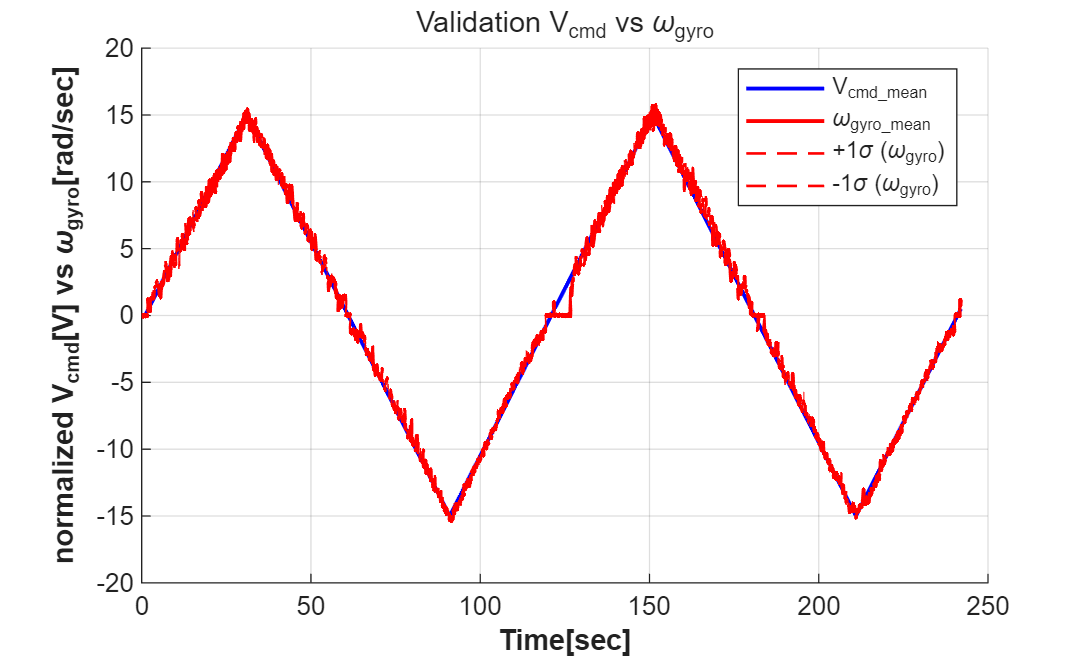

Vali_plot('tri');

% Vali_plot('sin');

## 3. Bode 

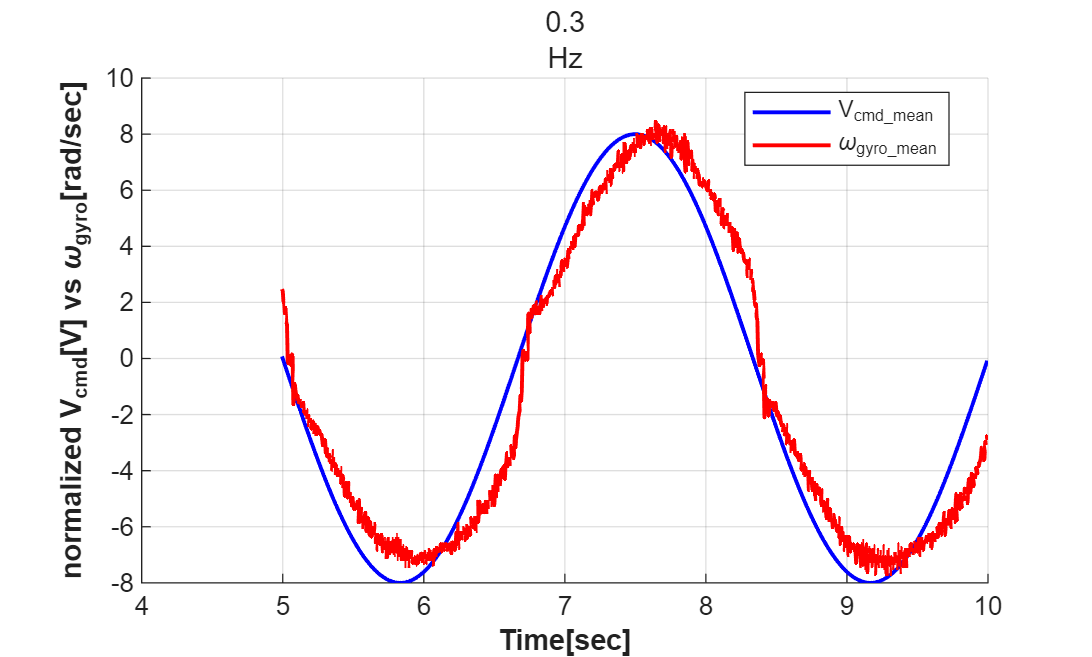

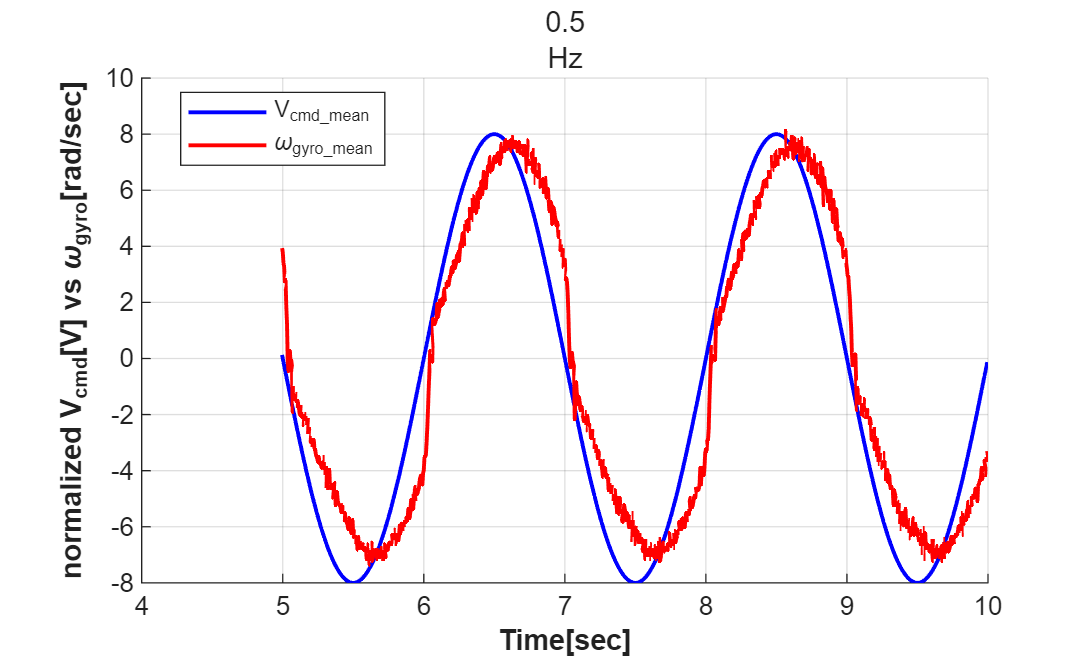

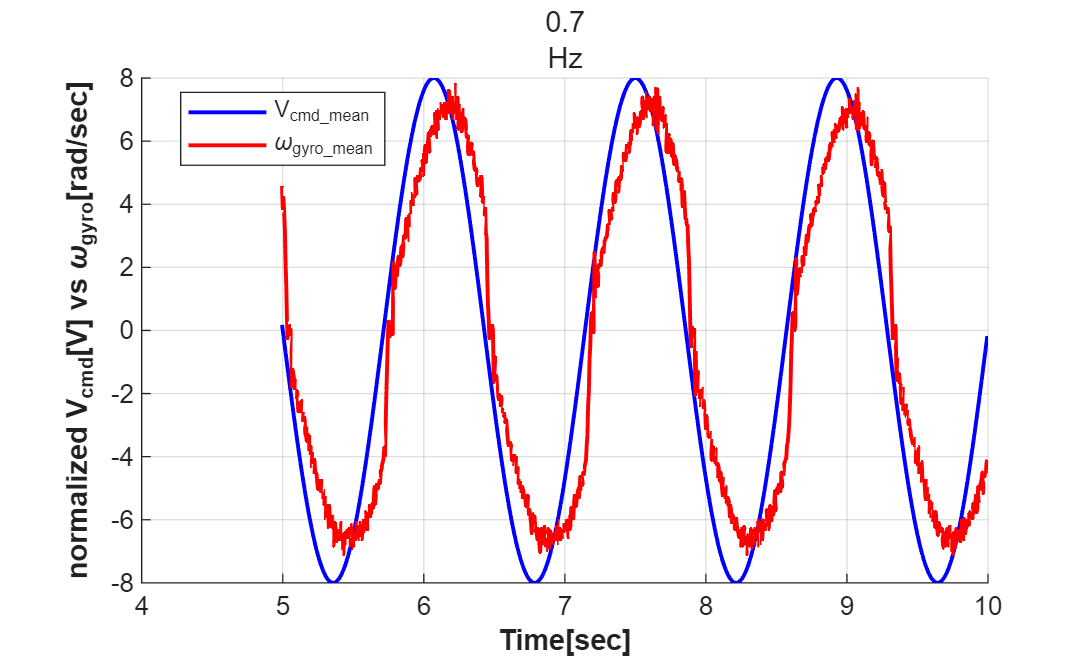

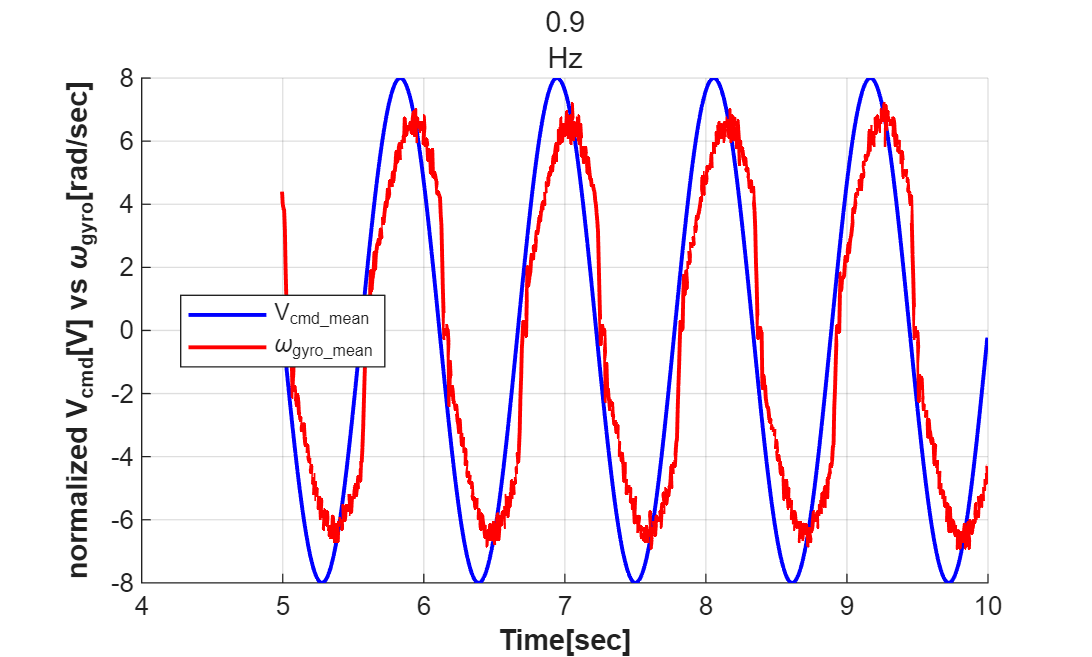

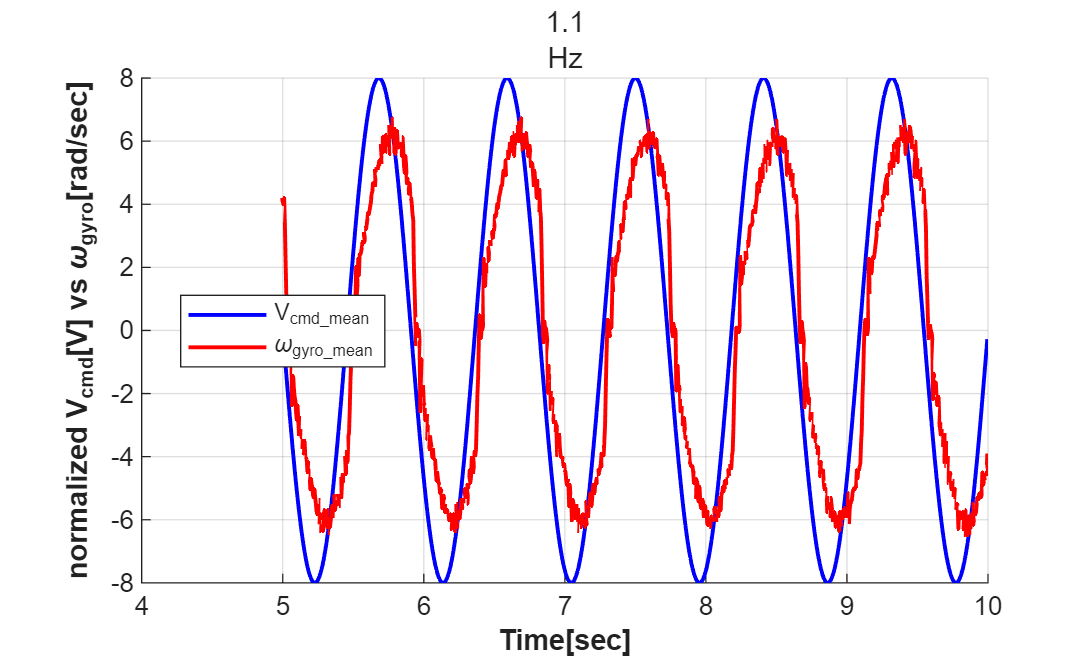

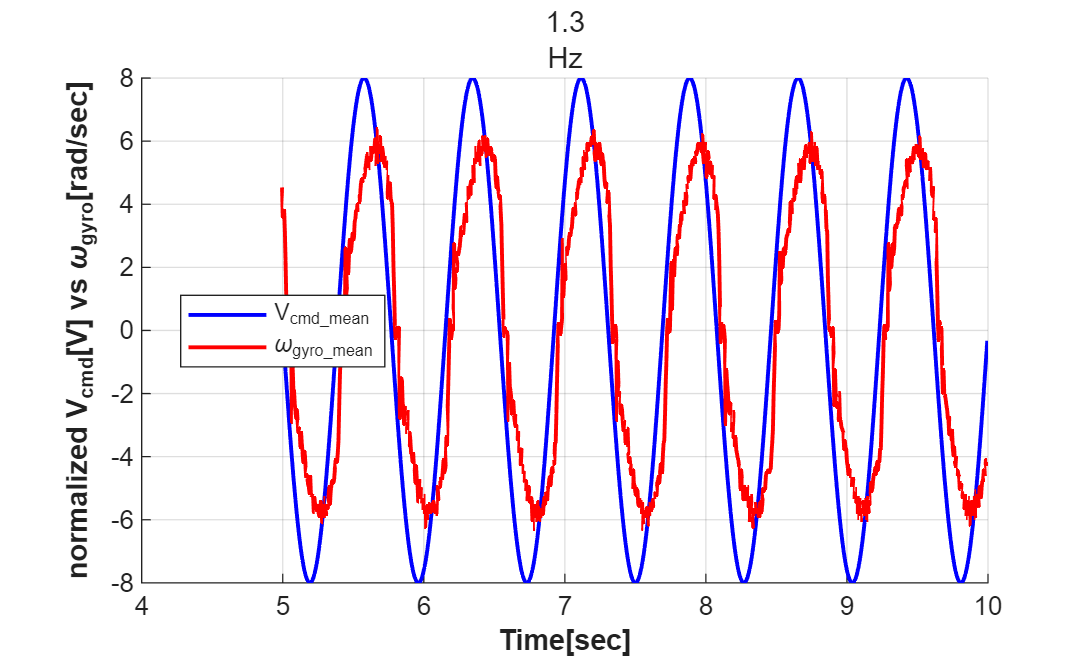

%From now on, the path is unified: 
path = '..\data\BodeMag\';

%3.1
generate_bode_plot(path);
%3.2 
BODE_plot(path); 

## 4. Obtain Transfer Function  


국소 최솟값을 찾았습니다.

기울기의 크기가 최적성 허용오차의
값보다 작기 때문에 최적화가 완료되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 함수 허용오차의 
값보다 작기 때문에 lsqcurvefit이(가) 중지되었습니다.

<중지 기준 세부 정보>

--- Phase Fitting Result_2nd ---
wn_2nd   = 471.5106 rad/s = 75.0432 Hz
zeta_2nd = 17.3058
DC gain_2nd = 0.9729

--- invfreqs Result (refere

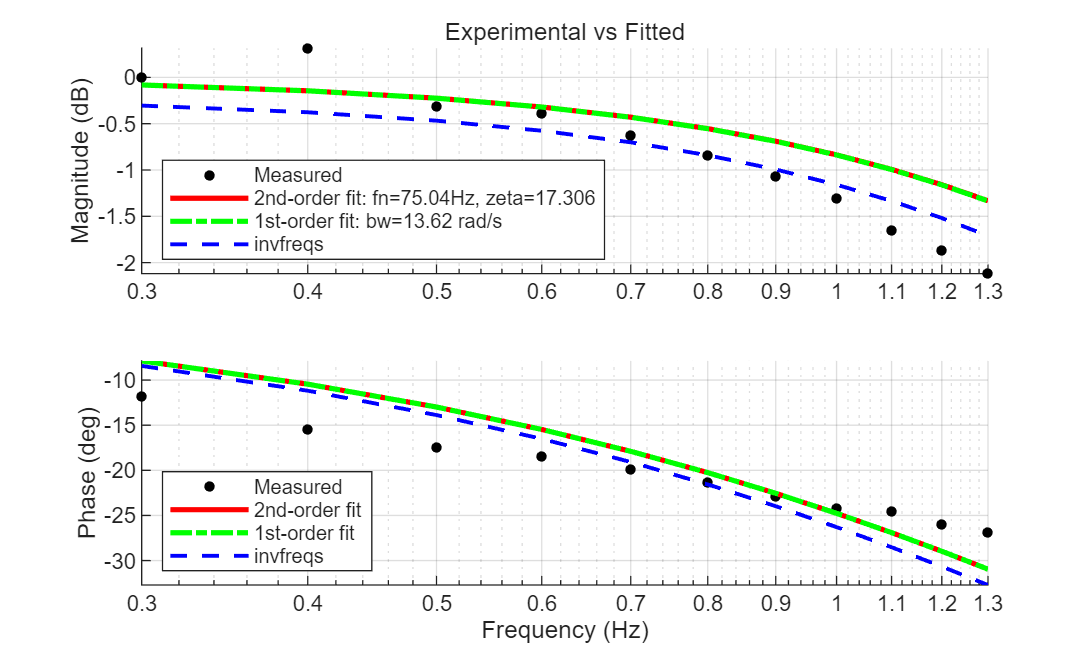

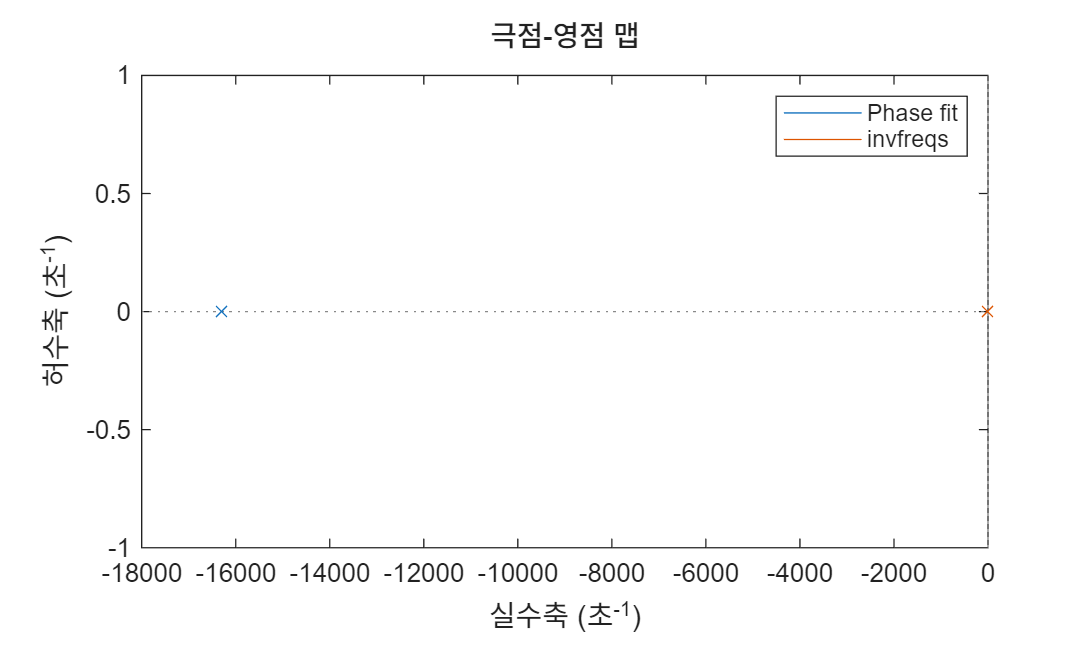

%4.1
Trans_func(path);


국소 최솟값을 찾았습니다.

기울기의 크기가 최적성 허용오차의
값보다 작기 때문에 최적화가 완료되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 함수 허용오차의 
값보다 작기 때문에 lsqcurvefit이(가) 중지되었습니다.

<중지 기준 세부 정보>

--- Phase Fitting Result_2nd ---
wn_2nd   = 471.5106 rad/s = 75.0432 Hz
zeta_2nd = 17.3058
DC gain_2nd = 0.9729

--- invfreqs Result (refere

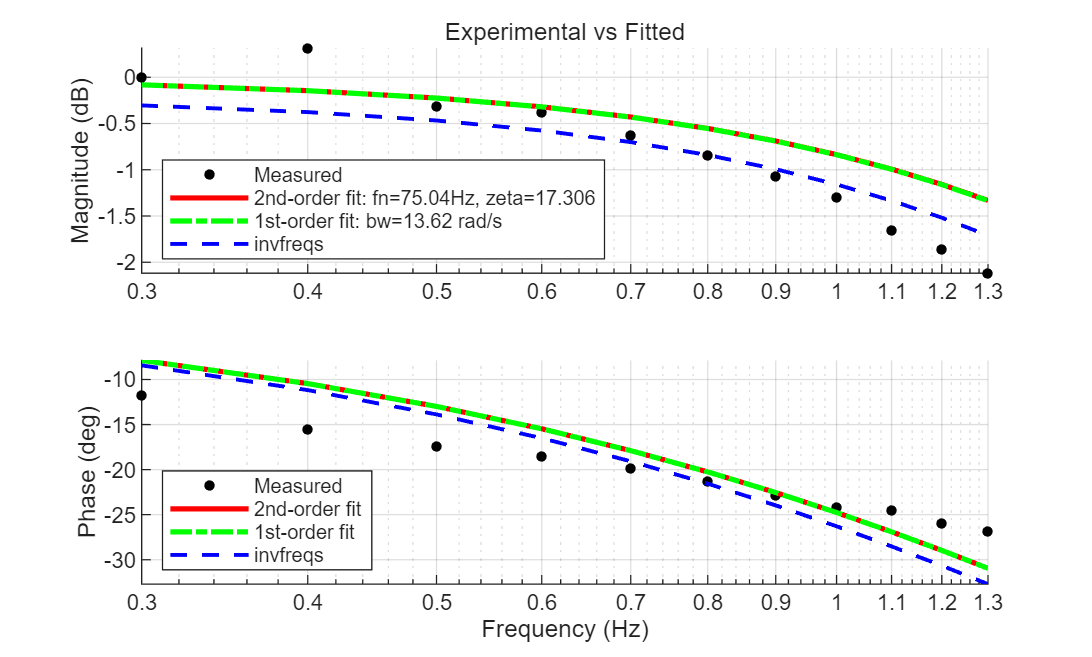

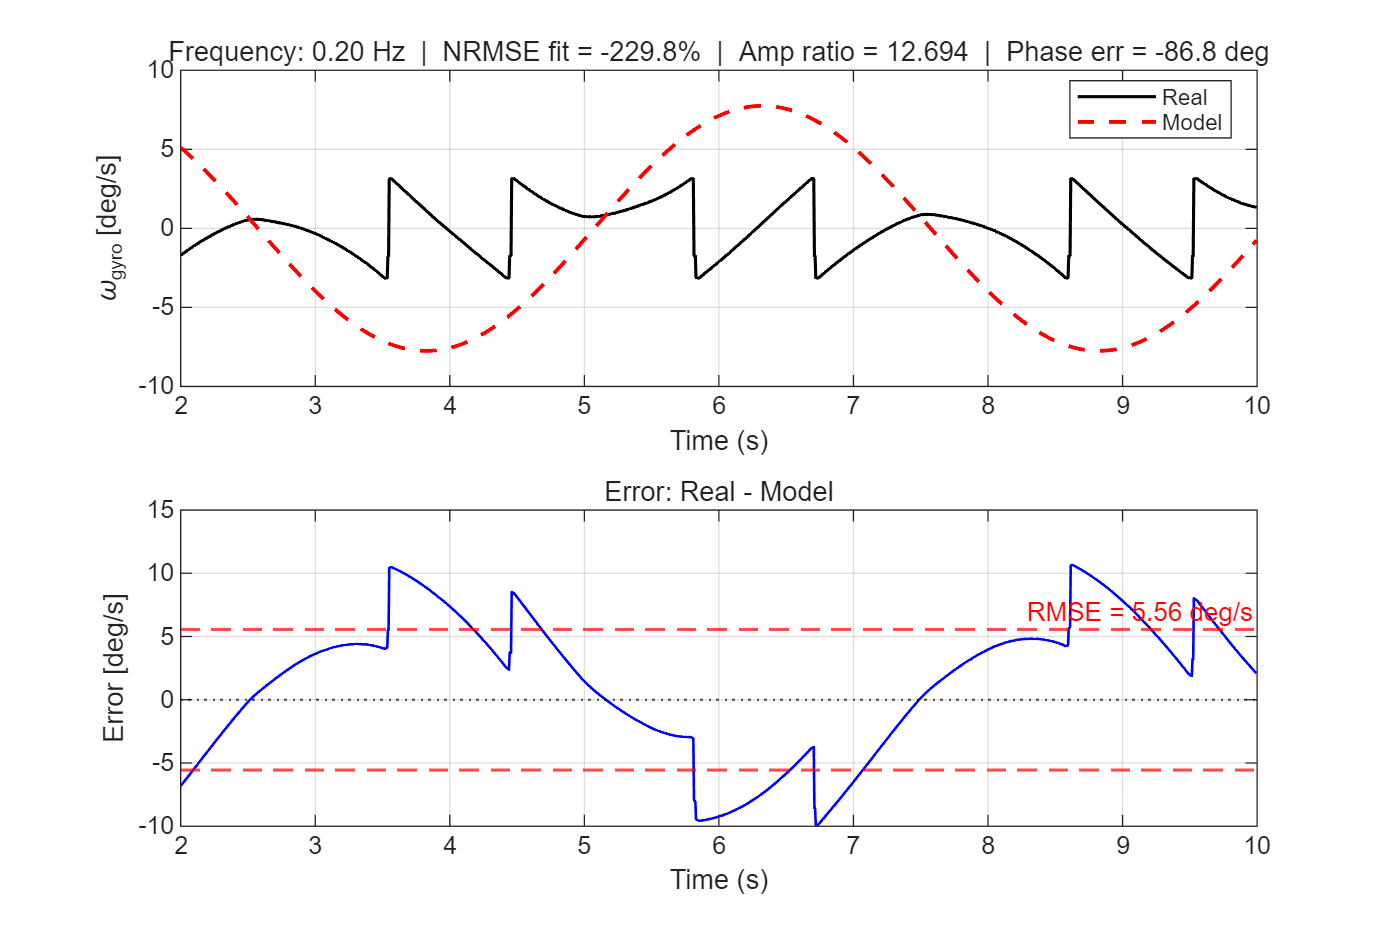

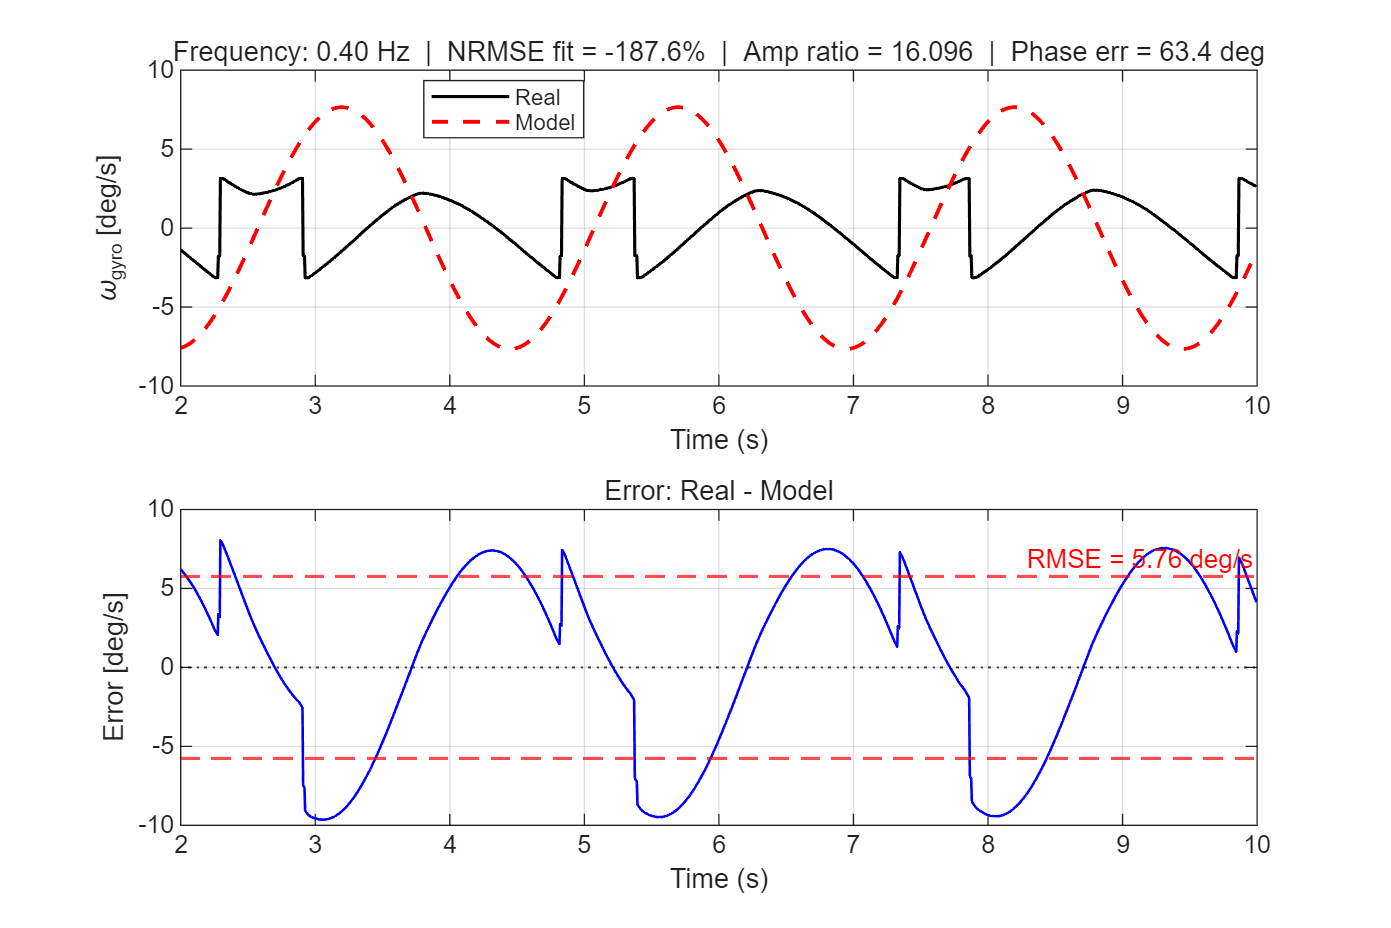

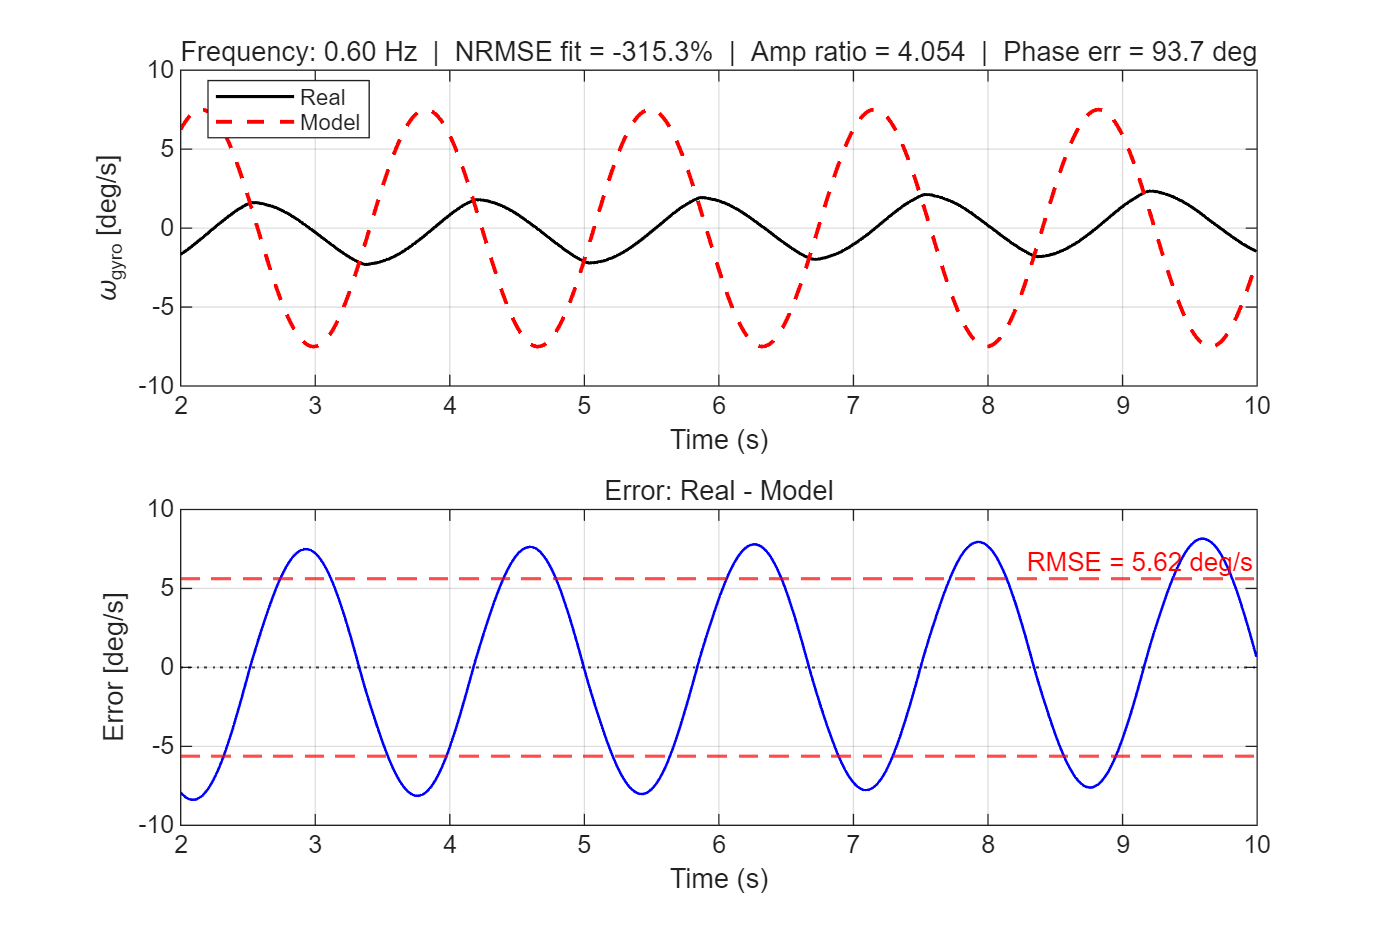

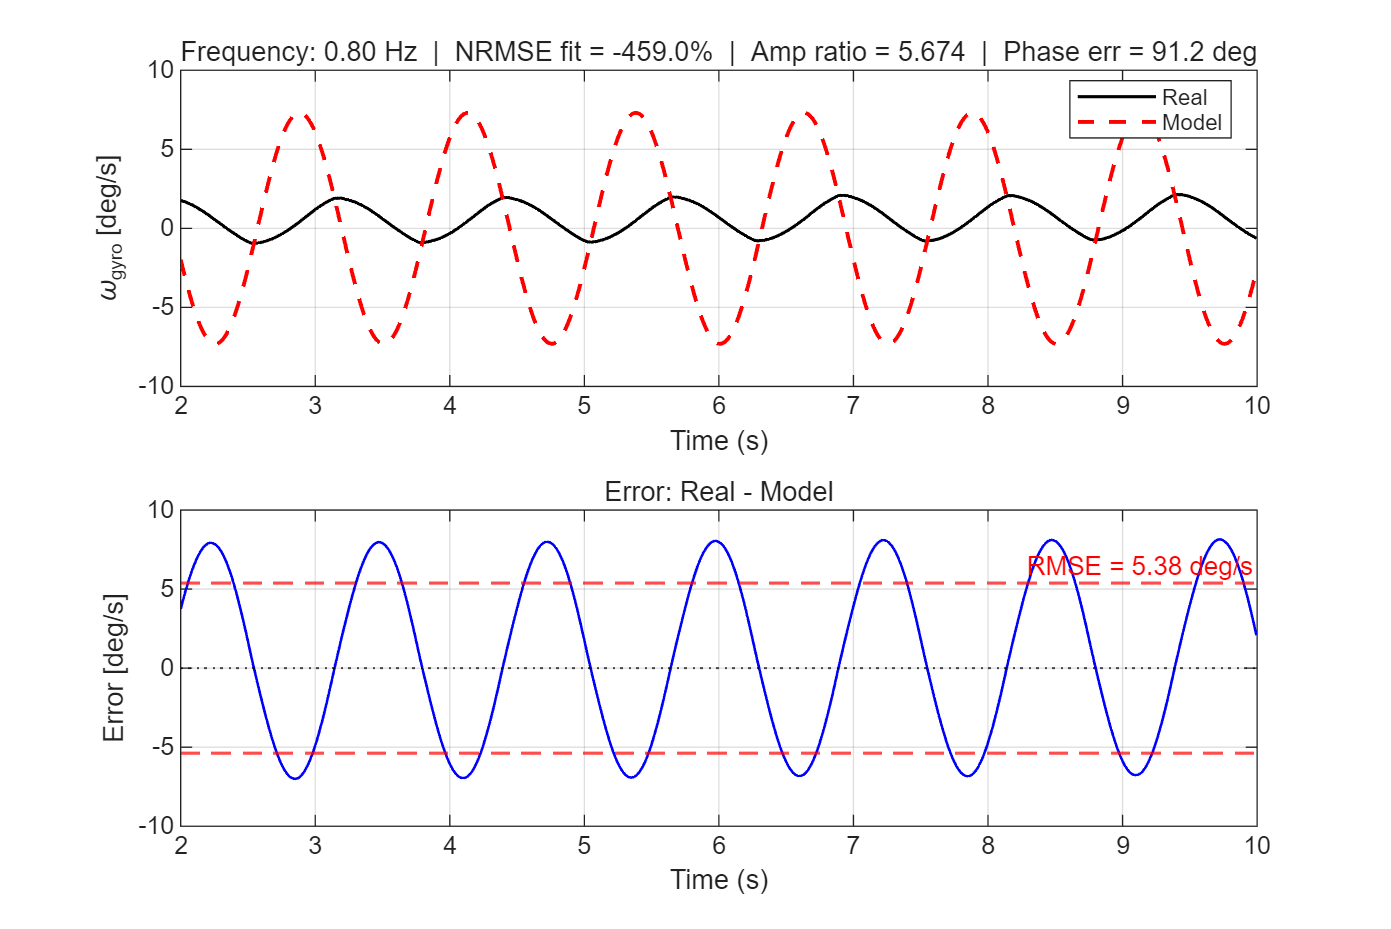

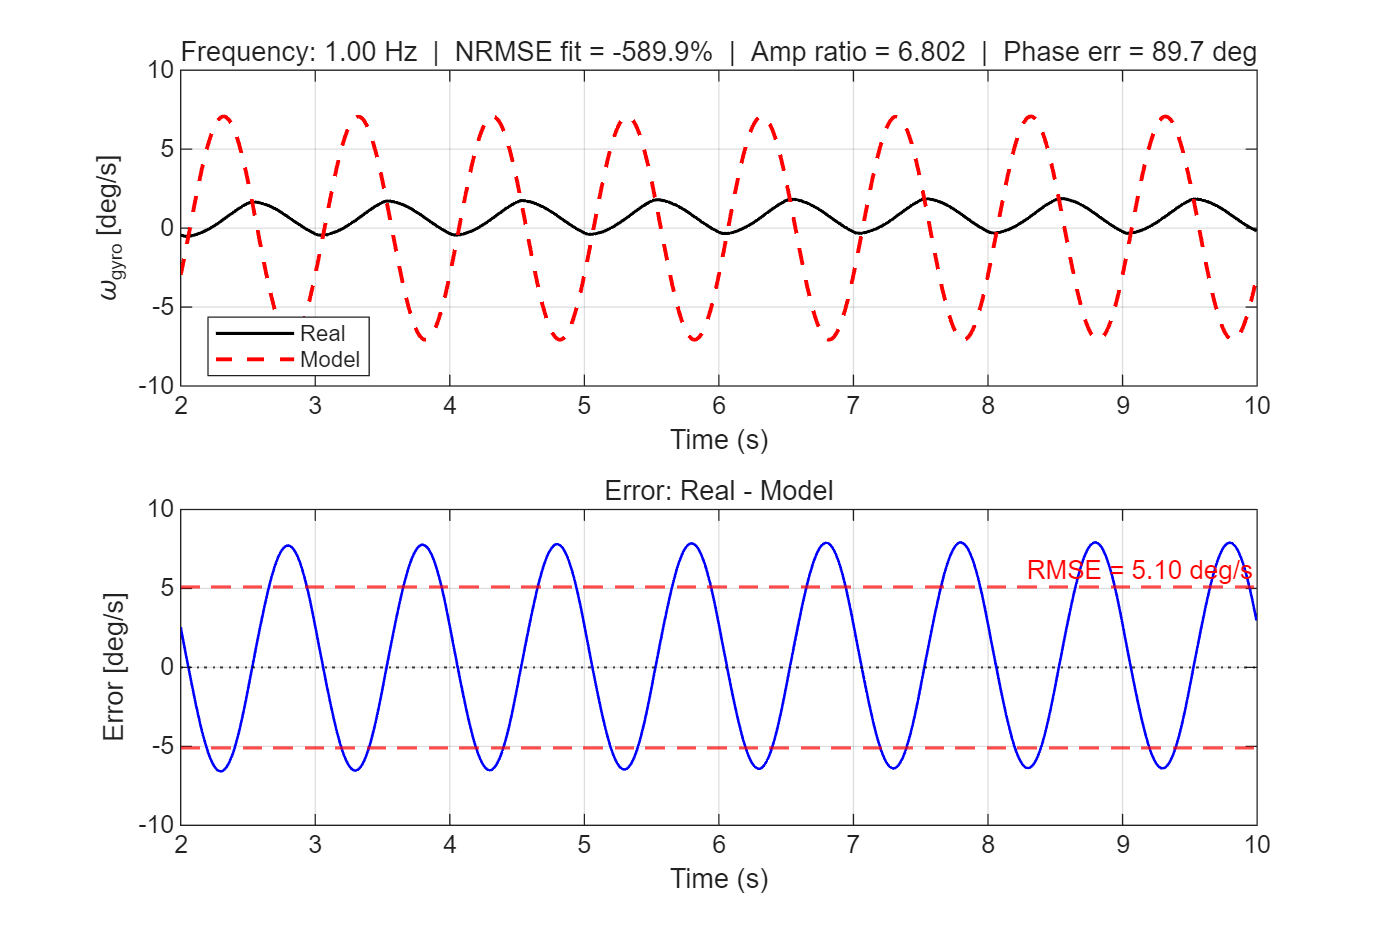

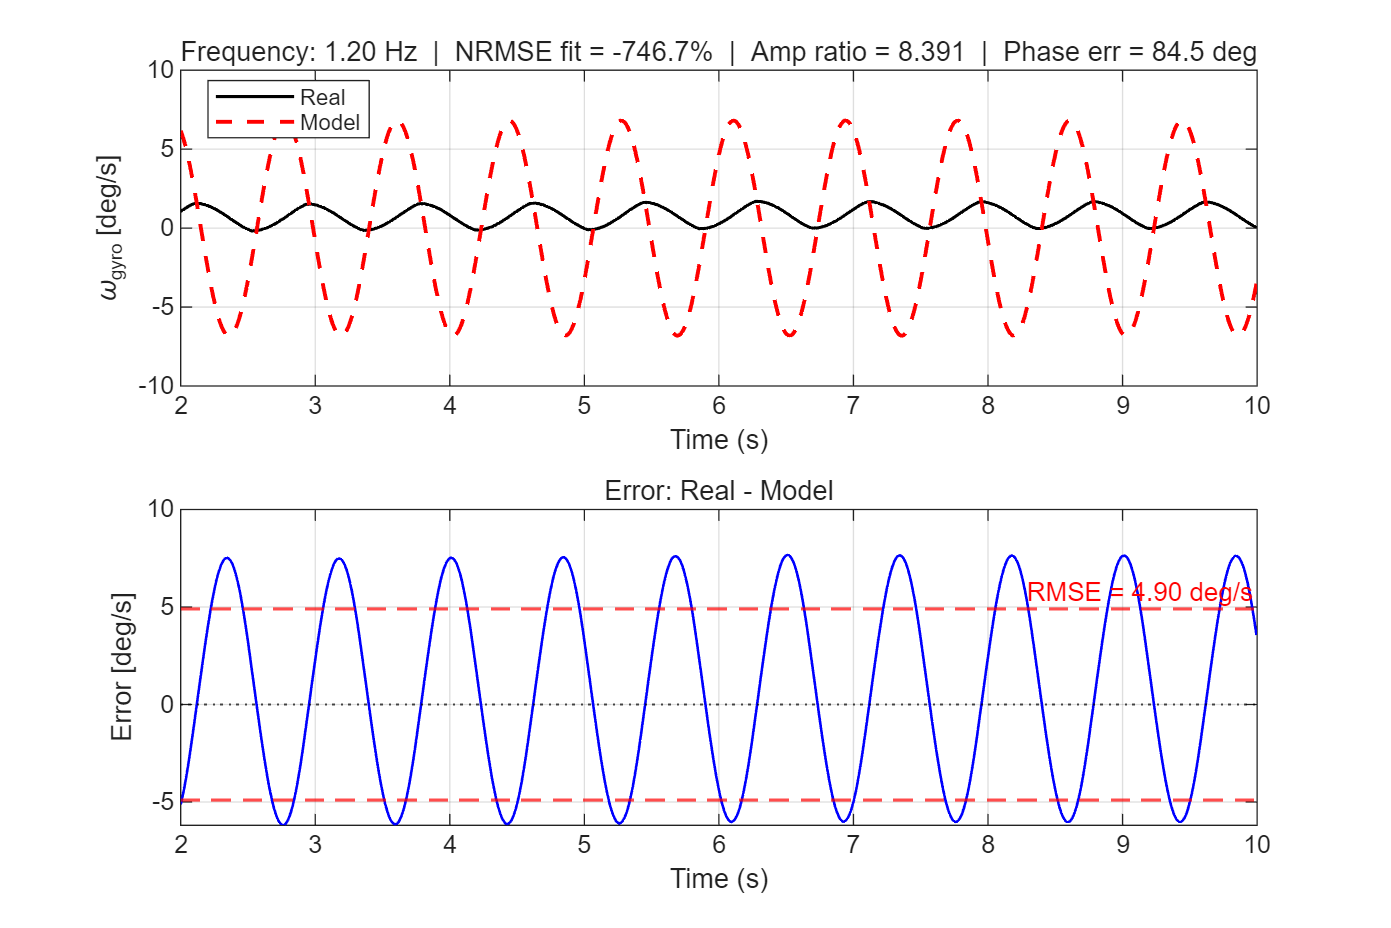

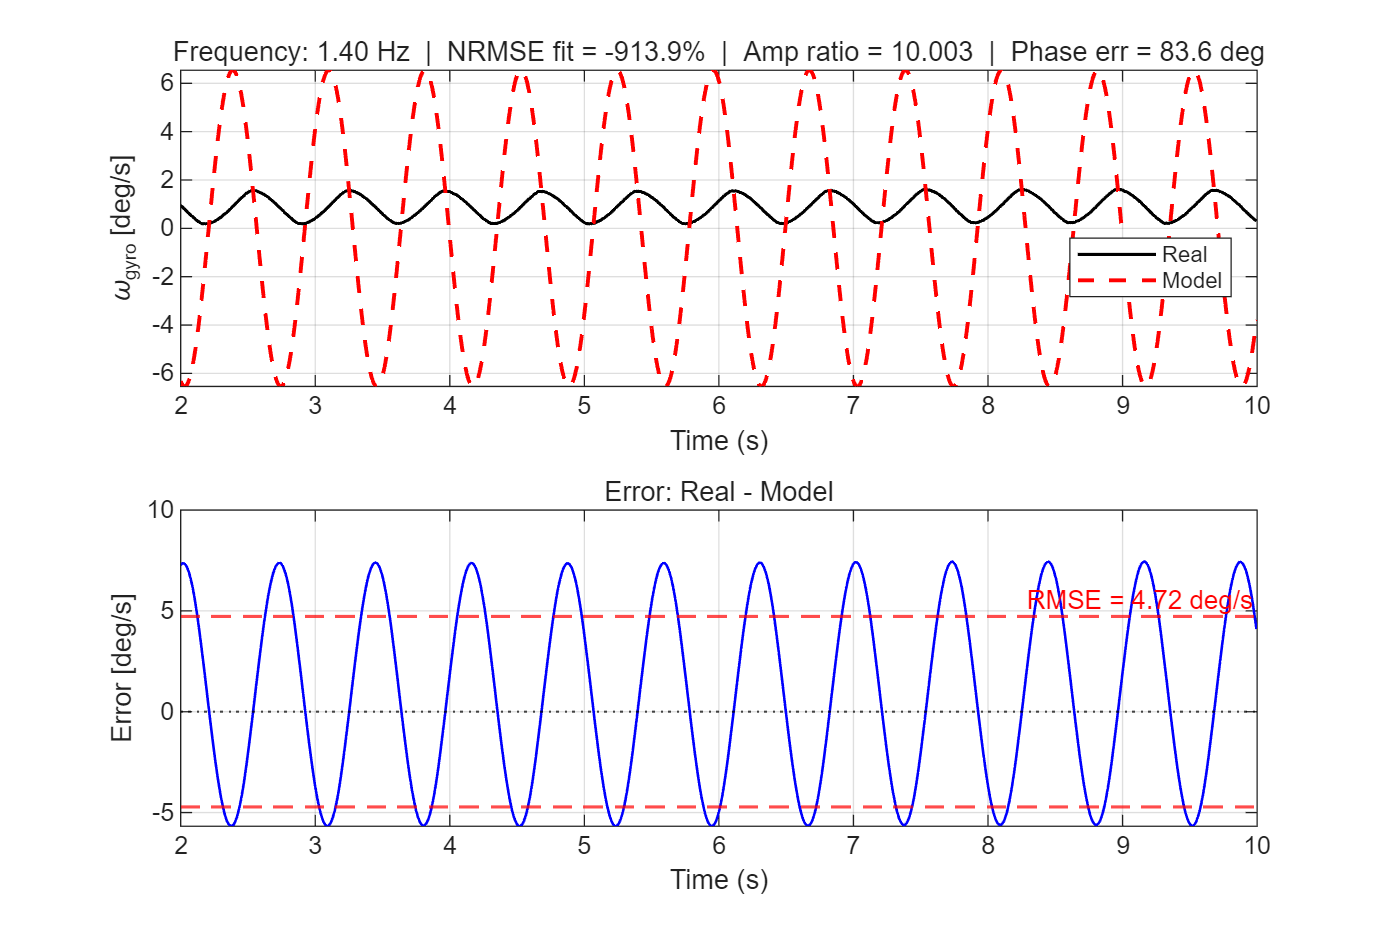


====== Validation Summary ======
Freq(Hz) RMSE       NRMSE fit%   Amp Ratio      Phase Err(deg)
------------------------------------------------------------
0.20     5.56       -229.8       12.694         -86.8         
0.40     5.76       -187.6       16.096         63.4          
0.60     5.62       -315.3       4.054          93.7          
0.80     5.38       -459.0       5.674          91.2          
1.00     5.10       -589.9       6.802          89.7          
1.20     4.90       -746.7       8.391          84.5          
1.40     4.72       -913.9       10.003         83.6          
1.60     4.51       -1032.4      11.524         83.3          
1.80     4.32       -1168.5      12.623         82.0          
2.00     4.07       -1251.6      13.464         80.3          


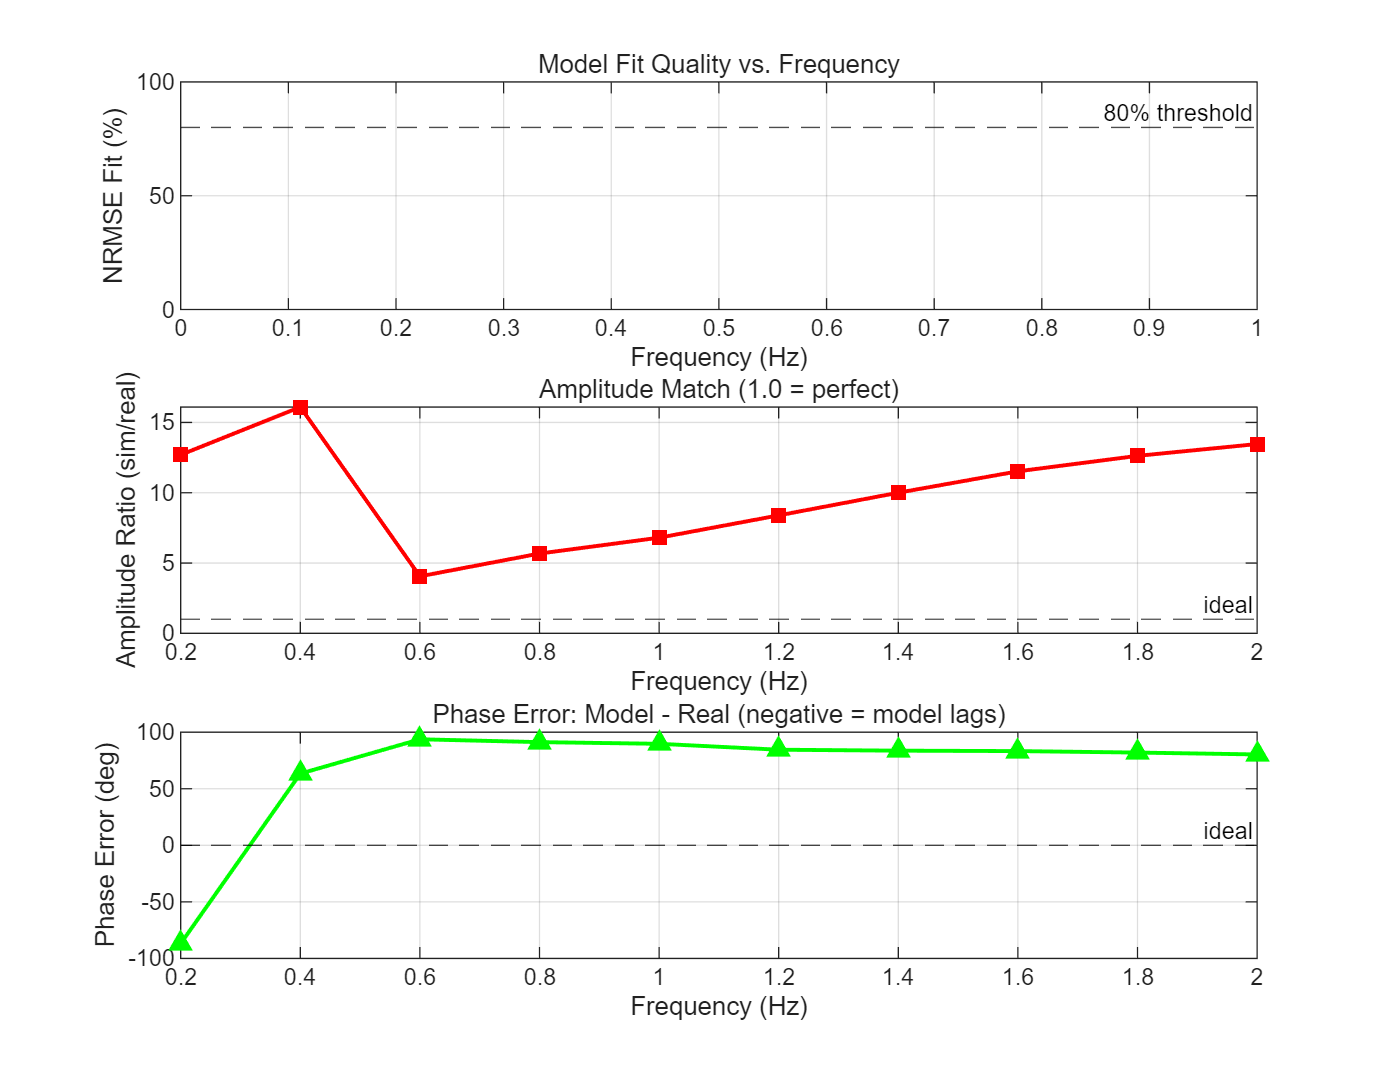

%4.2
Trans_func_valid(path); 